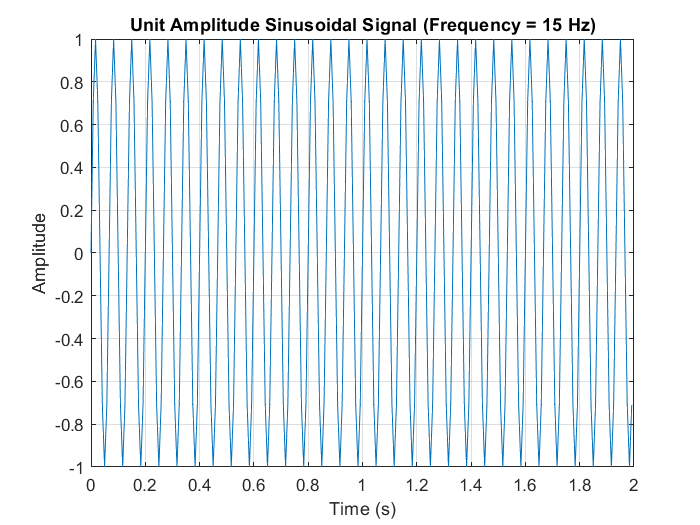

%Q1)
a = 1;            
duration = 2;        
sampling_rate = 120;  
Ts = 1 / sampling_rate;

% Calculate the total number of samples
N = duration * sampling_rate;
t = (0:N-1) * Ts;
f = 15 * a;
signal = sin(2 * pi * f * t);

figure;
plot(t, signal);
title(['Unit Amplitude Sinusoidal Signal (Frequency = ' num2str(f) ' Hz)']);
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

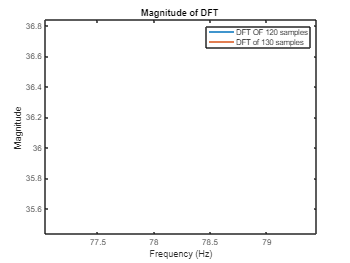


%Q1A,B,C)
a = 1;            
duration = 2;         
sampling_rate = 120; 
f = 15 * a; 
N = 120;

t = (0:N-1) / sampling_rate;
signal = sin(2 * pi * f* t);
fft_result = fft(signal(1:120));  
frequencies = (0:119) * (sampling_rate / 120);
magnitude3 = abs(fft_result);
figure;
A=plot(frequencies, magnitude3);
title(' DFT of First 120 Samples');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
hold on;

N2=130;
t2 = (0:N2-1) / sampling_rate;
signal = sin(2 * pi * f* t2);
fft_result2 = fft(signal(1:130));  
frequencies2 = (0:129) * (sampling_rate / 130);
magnitude2 = abs(fft_result2);

B=plot(frequencies2, magnitude2);
title('Magnitude of DFT ');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
legend([A,B],'DFT OF 120 samples','DFT of 130 samples');
hold off;

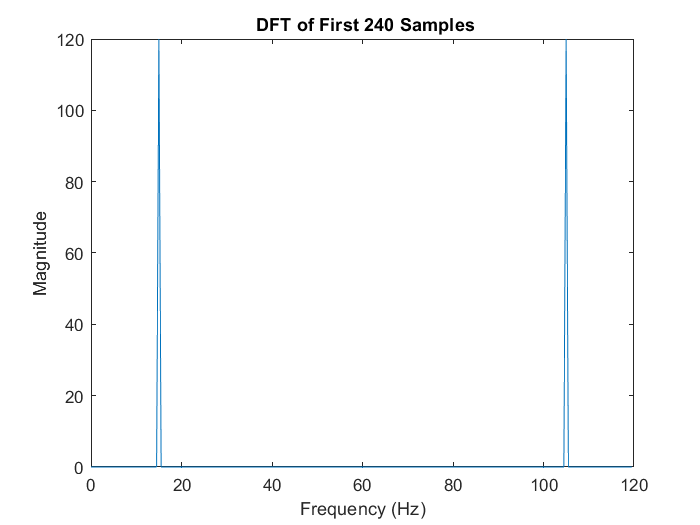



N1=240;
t9 = (0:N1-1) / sampling_rate;
signal = sin(2 * pi * f* t9);
fft_result3 = fft(signal(1:240));  
frequencies3 = (0:239) * (sampling_rate / 240);
magnitude3 = abs(fft_result3);
figure;
A=plot(frequencies3, magnitude3);
title(' DFT of First 240 Samples');
xlabel('Frequency (Hz)');
ylabel('Magnitude');